# Exercicio 1

Jesus Molina Roldan

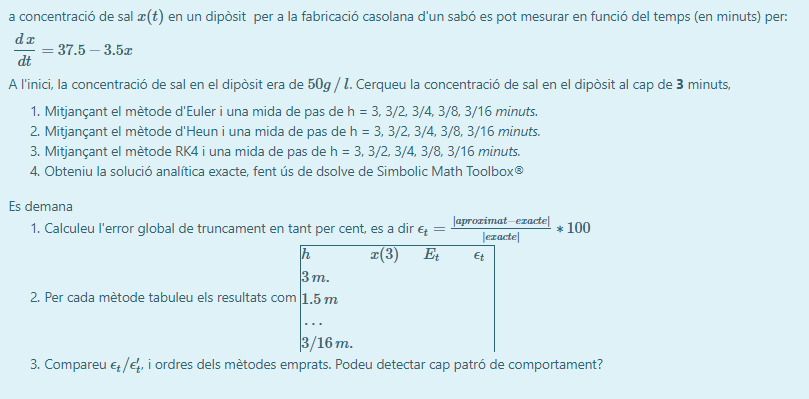

**1.**

syms x(t)
eqn = diff(x,t) == 37.5-3.5*x;
cond = x(0) == 50;
Sol(t) = dsolve(eqn,cond);
a = 0; alpha = 50;    % y(a) = alpha
b = 3;               % y(b) = ...
f = @(x,t)37.5-3.5*x;
h = ones(1,5)*3;
[ Y1 ] = Euler( f,a,b,h(1),alpha);
h = ones(1,5)*3;
p = (ones(1,5)*2).^(0:4);
h = h./p;
Y = ones(1,5);
for i = 1:5
    h_aux = h(i)
    [s] = Euler( f,a,b,h_aux,alpha);
    Y(i) = s(end);
end

h_aux =      3


h_aux =      1.500000000000000e+00


h_aux =      7.500000000000000e-01


h_aux =      3.750000000000000e-01


h_aux =      1.875000000000000e-01


ans =      5.000000000000000e+01     5.037500000000000e+01     5.074965000000000e+01     5.112395000000000e+01     5.149790000000000e+01     5.187150000000000e+01     5.224475000000000e+01     5.261765000000000e+01     5.299020000000000e+01     5.336240000000000e+01     5.373425000000000e+01     5.410575000000000e+01     5.447690000000000e+01     5.484770000000000e+01     5.521815000000000e+01     5.558825000000000e+01     5.595800000000001e+01     5.632740000000000e+01     5.669645000000001e+01     5.706515000000000e+01     5.743350000000000e+01     5.780150000000000e+01     5.816915000000000e+01     5.853645000000000e+01     5.890340000000000e+01     5.927000000000000e+01     5.963625000000000e+01     6.000215000000001e+01     6.036770000000001e+01     6.073290000000001e+01     6.109775000000000e+01     6.146225000000000e+01     6.182640000000001e+01     6.219020000000000e+01     6.255365000000000e+01     6.291675000000001e+01     6.327950000000001e+01     6.364190000000001e+01     6

[ET] = Et(double(ySol(3)), Y);
[error] = et(double(ySol(3)), Y);
[h' Y'   ET' error']

ans =      3.000000000000000e+00     1.625000000000000e+02     1.594502129316321e+02     5.228240836399249e+03
     1.500000000000000e+00     1.546250000000000e+02     1.515752129316321e+02     4.970026088173747e+03
     7.500000000000000e-01     1.506875000000000e+02     1.476377129316321e+02     4.840918714060995e+03
     3.750000000000000e-01     1.487187500000000e+02     1.456689629316321e+02     4.776365027004620e+03
     1.875000000000000e-01     1.477343750000000e+02     1.446845879316321e+02     4.744088183476432e+03


**2.**

syms x(t)
eqn = diff(x,t) == 37.5-3.5*x;
cond = x(0) == 50;
Sol(t) = dsolve(eqn,cond);
a = 0; alpha = 50;    % y(a) = alpha
b = 3;               % y(b) = ...
f = @(x,t)37.5-3.5*x;
h = ones(1,5)*3;
[ Y1 ] = Euler( f,a,b,h(1),alpha);
h = ones(1,5)*3;
p = (ones(1,5)*2).^(0:4);
h = h./p;
Y = ones(1,5);
for i = 1:5
    h_aux = h(i);
    [s] = Heun( f,a,b,h_aux,alpha);
    Y(i) = s(end);
end
[ET] = Et(double(ySol(3)), Y);
[error] = et(double(ySol(3)), Y);
[h' Y'   ET' error']

ans =      3.000000000000000e+00     1.467500000000000e+02     1.437002129316321e+02     4.711811339948244e+03
     1.500000000000000e+00     1.467500000000000e+02     1.437002129316321e+02     4.711811339948244e+03
     7.500000000000000e-01     1.467500000000000e+02     1.437002129316321e+02     4.711811339948244e+03
     3.750000000000000e-01     1.467500000000000e+02     1.437002129316321e+02     4.711811339948244e+03
     1.875000000000000e-01     1.467500000000000e+02     1.437002129316321e+02     4.711811339948244e+03


3.

syms x(t)
eqn = diff(x,t) == 37.5-3.5*x;
cond = x(0) == 50;
Sol(t) = dsolve(eqn,cond);
a = 0; alpha = 50;    % y(a) = alpha
b = 3;               % y(b) = ...
f = @(x,t)37.5-3.5*x;
h = ones(1,5)*3;
[ Y1 ] = Euler( f,a,b,h(1),alpha);
h = ones(1,5)*3;
p = (ones(1,5)*2).^(0:4);
h = h./p;
Y = ones(1,5);
for i = 1:5
    h_aux = h(i);
    [s] = RK4( f,a,b,h_aux,alpha);
    Y(i) = s(end);
end
[ET] = Et(double(ySol(3)), Y);
[error] = et(double(ySol(3)), Y);
[h' Y'   ET' error']

ans =      3.000000000000000e+00     1.467500000000000e+02     1.437002129316321e+02     4.711811339948244e+03
     1.500000000000000e+00     1.467500000000000e+02     1.437002129316321e+02     4.711811339948244e+03
     7.500000000000000e-01     1.467500000000000e+02     1.437002129316321e+02     4.711811339948244e+03
     3.750000000000000e-01     1.467500000000000e+02     1.437002129316321e+02     4.711811339948244e+03
     1.875000000000000e-01     1.467500000000000e+02     1.437002129316321e+02     4.711811339948244e+03


function [error_relativo] = et(valor_exacto, valor_aproximado)
    error_relativo = (abs(valor_exacto-valor_aproximado)./abs(valor_exacto))*100;
end
function [error_absoluto] = Et(valor_exacto, valor_aproximado)
    error_absoluto = abs(valor_exacto-valor_aproximado);
end